% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

k = 5;
d = 10;

lam = 5;

T = lam * eye(k) + abs(randn(k, k));
T = diag(sum(T, 1)) \ T ;

O = zeros(d, k);

for i = 1:k
    O(:, i) = binopdf(1:d, d, 0.5 * rand + 0.25);
end
O = Stochasticize(O);


if(rank(T) ~= k || rank(O) ~= k)
error("Insuffucient rank: Rank of T: " + rank(T) + " - and Rank of O: " + rank(O) + " - must be at least: " + k);
end

% k = 2;
% d = 6;
% 
% T = [.9 .1; .05 .95];
% 
% O = [1/6, 1/6, 1/6, 1/6, 1/6, 1/6;...
% 7/12, 1/12, 1/12, 1/12, 1/12, 1/12];


k = 3;
d = 10;

T = [8/10, 1/15, 1/6; 
    1/10, 13/15, 1/6; 
    1/10, 1/15, 2/3];

O = [6/15, 1/20, 1/50;
    1/15, 11/20, 1/50;
    1/15, 1/20, 1/50;
    1/15, 1/20, 21/50;
    1/15, 1/20, 21/50;
    1/15, 1/20, 1/50;
    1/15, 1/20, 1/50;
    1/15, 1/20, 1/50;
    1/15, 1/20, 1/50;
    1/15, 1/20, 1/50;];


eig(T)

ans =     1.0000
    0.7549
    0.5785


Generate an observational sequence based on the defined HMM

T_seq = 1e5;

[seq,states] = hmmgenerate(T_seq,T',O');

likelystates = hmmviterbi(seq, T', O');
sum(states==likelystates)/T_seq;

Generate HMM estimate based on emperical methods (Baum-Welch?). Note that this uses the states as an input.

tic
[T_hat_k, O_hat_k] = hmmestimate(seq, states);
toc

Elapsed time is 0.008252 seconds.




T_GUESS = rand(k, k);
T_GUESS = Stochasticize(T_GUESS);

O_GUESS = rand(d, k);
O_GUESS = Stochasticize(O_GUESS);

% T_GUESS = T_hat_k;
% O_GUESS = O_hat_k;

tic
[T_hat, O_hat] = hmmtrain(seq, T_GUESS', O_GUESS');
toc

Elapsed time is 153.549921 seconds.


Generate Probability Density Tensors

%% Section
[P1, P21, P31, P32, P321, P312] = CreateMarginalProbabilities(seq, d);


Estimate the HMM using LearnHKZ

triple_seq = zeros(length(seq)-2, 3);
for i = 1:length(triple_seq)
    triple_seq(i, :) = [seq(i), seq(i+1), seq(i+2)];
end

tic
% [O_hat_hkz, T_hat_hkz, Pi_hat_hkz] = LearnHKZ(P1, P21, P31, P321, d, k)
[b1hat, binfhat, Bxhat, O_hat_hkz, PINIThat, T_hat_hkz] = learnHKZ2(triple_seq,k,d)

b1hat =    -0.3907
    0.0676
   -0.0067


binfhat =    -2.3336
    1.2880
   -0.2267


Bxhat = Bxhat(:,:,1) =

    0.1023   -0.1338    0.1952
   -0.0444    0.1514   -0.1791
    0.0349   -0.0933    0.1407


Bxhat(:,:,2) =

    0.4066    0.2804   -0.0365
    0.0877    0.1061   -0.0292
   -0.0058   -0.0136    0.0237


Bxhat(:,:,3) =

    0.0488   -0.0038    0.0190
   -0.0020    0.0335   -0.0166
    0.0045   -0.0117    0.0256


Bxhat(:,:,4) =

    0.0900   -0.1280   -0.1513
   -0.0392    0.1454    0.1264
   -0.0248    0.0757    0.1271


Bxhat(:,:,5) =

    0.0880   -0.1259   -0.1459
   -0.0398    0.1391    0.1300
   -0.0262    0.0711    0.1410


Bxhat(:,:,6) =

    0.0486   -0.0078    0.0281
   -0.0009    0.0347   -0.0195
    0.0035   -0.0109    0.0258


Bxhat(:,:,7) =

    0.0475   -0.0051    0.0178
   -0.0024    0.0330   -0.0257
    0.0044   -0.0120    0.0214


Bxhat(:,:,8) =

    0.0484   -0.0094    0.0225
   -0.0006    0.0318   -0.0161
    0.0029   -0.0090    0.0243


Bxhat(:,:,9) =

    0.0481    0.0013    0.0193
   -0.0006    0.0391   -0.0174
    0.0037   -0.0142    0.

O_hat_hkz =     0.4309    0.0558    0.0250
    0.5524    0.0576    0.0266
    0.0225    0.0494    0.0650
    0.4099    0.0525    0.0525
    0.4170    0.0462    0.0645
    0.0220    0.0502    0.0667
    0.0652    0.0482    0.0129
    0.0237    0.0483    0.0601
    0.0220    0.0539    0.0682
    0.0668    0.0449    0.0191


PINIThat =     0.3031
    1.1703
   -0.4324


T_hat_hkz =     0.3557    0.1180   -0.0775
    0.4612    4.6089    8.9995
    0.1055   -3.3211   -7.1722


toc

Elapsed time is 0.054194 seconds.


Estimate HMM using LearnAHK

% [T_hat_ahk, O_hat_ahk] = LearnAHK(P31, P32, P312, d, k)
tic
[O_hat_ahk, T_hat_ahk] = learnAHK2(triple_seq,k,d)

O_hat_ahk =     0.0552    0.0288    0.4238
    0.5519    0.0282    0.0544
    0.0495    0.0186    0.0733
    0.0484    0.4073    0.0671
    0.0475    0.4072    0.0631
    0.0512    0.0218    0.0682
    0.0503    0.0198    0.0700
    0.0543    0.0232    0.0619
    0.0488    0.0187    0.0683
    0.0468    0.0248    0.0681


T_hat_ahk =     0.8662    0.1629    0.1064
    0.0695    0.6475   -0.0245
    0.0643    0.1896    0.9181


toc

Elapsed time is 0.030259 seconds.


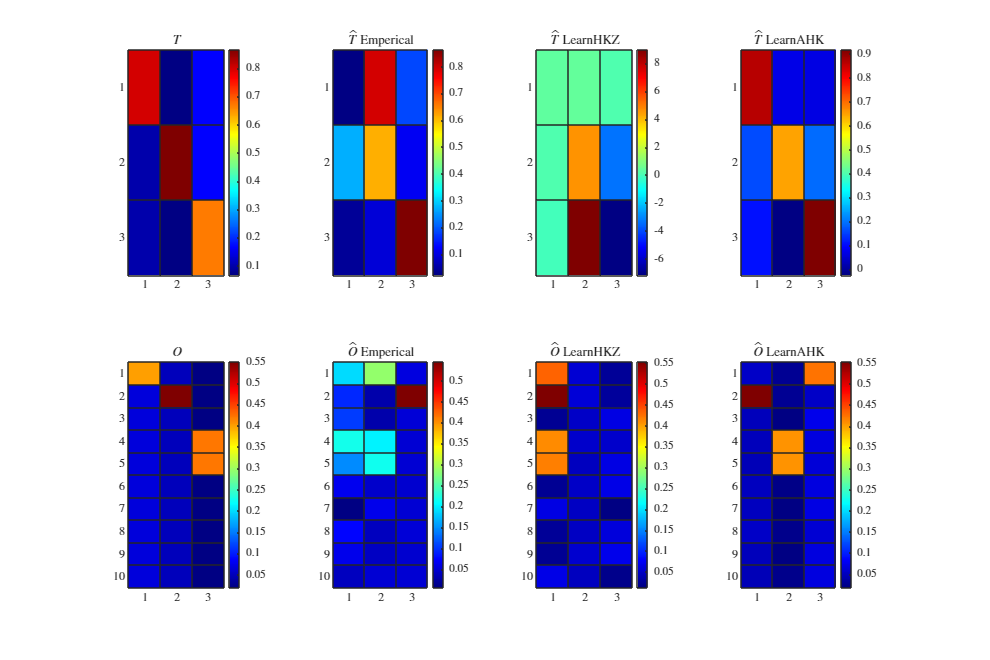


figure('Renderer', 'painters', 'Position', [10 10 900 600])
% figure()

subplot(2, 4, 1);
h = heatmap(T, Colormap=jet());
h.Title = '$T$';
h.Interpreter = 'latex';

subplot(2, 4, 2);
h = heatmap(T_hat, Colormap=jet());
h.Title = '$\hat{T}$ Emperical';
h.Interpreter = 'latex';

subplot(2, 4, 3);
h = heatmap(T_hat_hkz', Colormap=jet());
h.Title = '$\hat{T}$ LearnHKZ';
h.Interpreter = 'latex';

subplot(2, 4, 4);
h = heatmap(T_hat_ahk', Colormap=jet());
h.Title = '$\hat{T}$ LearnAHK';
h.Interpreter = 'latex';



subplot(2, 4, 5);
h = heatmap(O, Colormap=jet());
h.Title = '$O$';
h.Interpreter = 'latex';

subplot(2, 4, 6);
h = heatmap(O_hat', Colormap=jet());
h.Title = '$\hat{O}$ Emperical';
h.Interpreter = 'latex';

subplot(2, 4, 7);
h = heatmap(O_hat_hkz, Colormap=jet());
h.Title = '$\hat{O}$ LearnHKZ';
h.Interpreter = 'latex';

subplot(2, 4, 8);
h = heatmap(O_hat_ahk, Colormap=jet());
h.Title = '$\hat{O}$ LearnAHK';
h.Interpreter = 'latex';

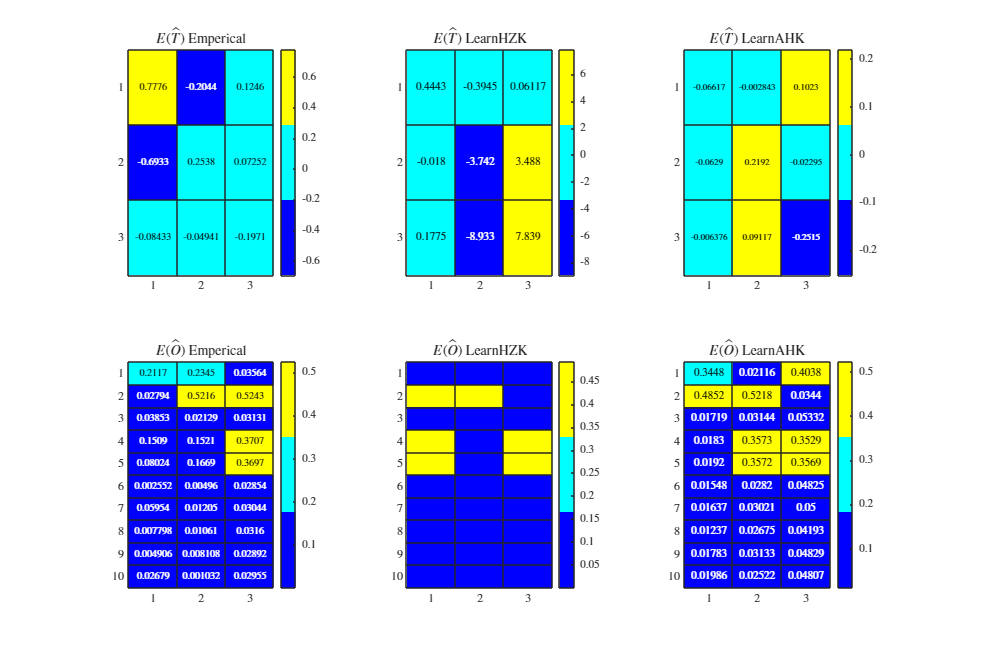

figure('Renderer', 'painters', 'Position', [10 10 900 600])
% figure()

subplot(2, 3, 1);
h = heatmap((T - T_hat'), Colormap=jet(size(T, 1)));
h.Title = '$E(\hat{T})$ Emperical';
h.Interpreter = 'latex';

subplot(2, 3, 2);
h = heatmap((T - T_hat_hkz'), Colormap=jet(size(T, 1)));
h.Title = '$E(\hat{T})$ LearnHZK';
h.Interpreter = 'latex';

subplot(2, 3, 3);
h = heatmap((T - T_hat_ahk'), Colormap=jet(size(T, 1)));
h.Title = '$E(\hat{T})$ LearnAHK';
h.Interpreter = 'latex';


subplot(2, 3, 4);
h = heatmap(abs(O-O_hat'), Colormap=jet(size(O, 2)));
h.Title = '$E(\hat{O})$ Emperical';
h.Interpreter = 'latex';

subplot(2, 3, 5);
h = heatmap(abs(O-O_hat_hkz), Colormap=jet(size(O, 2)));
h.Title = '$E(\hat{O})$ LearnHZK';
h.Interpreter = 'latex';

subplot(2, 3, 6);
h = heatmap(abs(O - O_hat_ahk), Colormap=jet(size(O, 2)));
h.Title = '$E(\hat{O})$ LearnAHK';
h.Interpreter = 'latex';